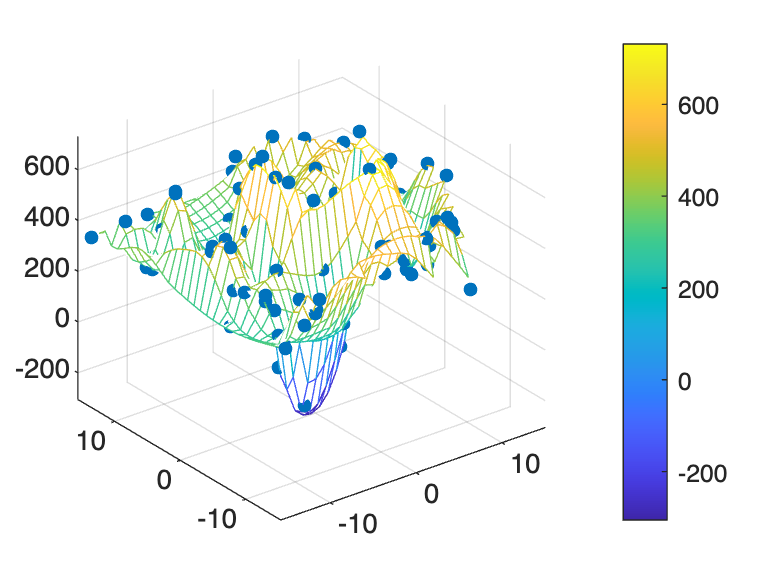

x = rand(100, 1)*32 - 16;
y = rand(100, 1)*32 - 16;
r = sqrt(x.^2 + y.^2) + eps;
z = (2000*cos(r)./r) + 400;

xlin = linspace(min(x), max(x), 33);
ylin = linspace(min(y), max(y), 33);
[X, Y] = meshgrid(xlin, ylin);

%transpose x,y,z to make column vectors
Z = griddata(x, y, z, X, Y, 'cubic');
mesh(X, Y, Z);
axis tight; hold on;
plot3(x, y, z, '.', 'MarkerSize', 15);
colorbar